clear all;
clf;
load 'Q1\Julia.mat';
[n,m]=size(Julia);
a=double(Julia);
img_B=uint8(zeros(n,m));
img_G=uint8(zeros(n,m));
img_R=uint8(zeros(n,m));

for i=[2:n-1]
    for j=[2:m-1]
        x1=a(i-1,j)+a(i+1,j)+a(i,j-1)+a(i,j+1);%相邻4个
        x1=uint8(x1/4);
        x2=a(i-1,j-1)+a(i-1,j+1)+a(i+1,j-1)+a(i+1,j+1);%角上4个
        x2=uint8(x2/4);
        x3=a(i,j-1)+a(i,j+1);%左右2个
        x3=uint8(x3/2);
        x4=a(i-1,j)+a(i+1,j);%上下2个
        x4=uint8(x4/2);
        if mod(i,2)==1%奇数行
            if mod(j,2)==1%蓝色
                img_B(i,j)=uint8(a(i,j));
                img_G(i,j)=x1;
                img_R(i,j)=x2;
            else%绿色
                img_B(i,j)=x4;
                img_G(i,j)=uint8(a(i,j));
                img_R(i,j)=x3;
            end
        else
            if mod(j,2)==1%绿色
                img_B(i,j)=x4;
                img_G(i,j)=uint8(a(i,j));
                img_R(i,j)=x3;
            else%红色
                img_B(i,j)=x2;
                img_G(i,j)=x1;
                img_R(i,j)=uint8(a(i,j));
            end
        end
    end
end
img_B(1,1)=uint8(a(1,1));
img_G(1,1)=uint8((a(2,1)+a(1,2))/2);
img_R(1,1)=uint8(a(2,2));
img_B(n,1)=uint8(a(n,1));
img_G(n,1)=uint8((a(n-1,1)+a(n,2))/2);
img_R(n,1)=uint8(a(n-1,2));
img_B(1,m)=uint8(a(1,m-1));
img_G(1,m)=uint8(a(1,m));
img_R(1,m)=uint8(a(2,m));
img_B(n,m)=uint8(a(n,m-1));
img_G(n,m)=uint8(a(n,m));
img_R(n,m)=uint8(a(n-1,m));
for i=[2:n-1]
    if mod(i,2)==1
        img_B(i,1)=uint8(a(i,1));
        img_G(i,1)=uint8((a(i-1,1)+a(i,2)+a(i+1,1))/3);
        img_R(i,1)=uint8((a(i-1,2)+a(i+1,2))/2);
        img_B(i,m)=uint8(a(i,m-1));
        img_G(i,m)=uint8(a(i,m));
        img_R(i,m)=uint8((a(i-1,m)+a(i+1,m))/2);
    else
        img_B(i,1)=uint8((a(i-1,1)+a(i+1,1))/2);
        img_G(i,1)=uint8(a(i,1));
        img_R(i,1)=uint8(a(i,2));
        img_B(i,m)=uint8((a(i-1,m-1)+a(i+1,m-1))/2);
        img_G(i,m)=uint8((a(i-1,m)+a(i,m-1)+a(i+1,m))/3);
        img_R(i,m)=uint8(a(i,m));
    end
end
for i=[2:m-1]
    if mod(i,2)==1
        img_B(1,i)=uint8(a(1,i));
        img_G(1,i)=uint8((a(1,i-1)+a(2,i)+a(1,i+1))/3);
        img_R(1,i)=uint8((a(2,i-1)+a(2,i+1))/2);
        img_B(n,i)=uint8(a(n,i));
        img_G(n,i)=uint8((a(n,i-1)+a(n-1,i)+a(n,i+1))/3);
        img_R(n,i)=uint8((a(n-1,i-1)+a(n-1,i+1))/2);
    else
        img_B(1,i)=uint8((a(1,i-1)+a(1,i+1))/2);
        img_G(1,i)=uint8(a(1,i));
        img_R(1,i)=uint8(a(2,i));
        img_B(n,i)=uint8((a(n,i-1)+a(n,i+1))/2);
        img_G(n,i)=uint8(a(n,i));
        img_R(n,i)=uint8(a(n-1,i));
    end
end
result=cat(3,img_R,img_G,img_B);




sky=imread('Q1\sky.jpg');
fr=sky(:,:,1);
fg=sky(:,:,2);
fb=sky(:,:,3);
i=0.299*fr+0.587*fg+0.114*fb;
imean=sum(i(:));
frmean=sum(fr(:));fgmean=sum(fg(:));fbmean=sum(fb(:));
kr=imean/frmean;kg=imean/fgmean;kb=imean/fbmean;
gr=kr*fr;gg=kg*fg;gb=kb*fb;
whitebalance=cat(3,gr,gg,gb);



[m,n]=size(fr);
rmax=max(fr(:));gmax=max(fg(:));bmax=max(fb(:));
srgb=min([rmax,gmax,bmax]);
nr=sum(sum(fr>srgb));ng=sum(sum(fg>srgb));nb=sum(sum(fb>srgb));
nmax=max([nr,ng,nb]);
r=sort(fr(:),'descend');tr=r(nmax);
g=sort(fg(:),'descend');tg=g(nmax);
b=sort(fb(:),'descend');tb=b(nmax);
kr=srgb/tr;kg=srgb/tg;kb=srgb/tb;
gr=kr*fr;gg=kg*fg;gb=kb*fb;
colorbalance=cat(3,gr,gg,gb);

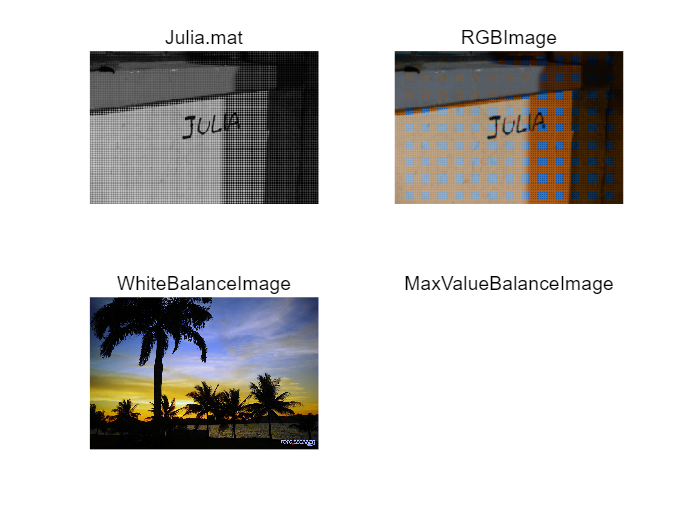


subplot(2,2,1);imshow(uint8(Julia));title('Julia.mat');
subplot(2,2,2);imshow(result);title('RGBImage');
subplot(2,2,3);imshow(whitebalance);title('WhiteBalanceImage')
subplot(2,2,4);imshow(colorbalance);title('MaxValueBalanceImage');